%startup_rvc;

L = [46 107 107 110]

L =     46   107   107   110


DHParamsSym = [0 L(1) 0 sym(pi)/2 0 0;
            0 0 L(2) 0 0 sym(pi)/2;
            0 0 L(3) 0 0 sym(pi)/2;
            0 0 L(4) 0 0 0];            

LnkSym(1) = Link(DHParamsSym(1,:));
LnkSym(2) = Link(DHParamsSym(2,:));
LnkSym(3) = Link(DHParamsSym(3,:));
LnkSym(4) = Link(DHParamsSym(4,:));


RSym = SerialLink(LnkSym,'name','PhantomXSym');

H_tool = [0 0 1 0;
          1 0 0 0;
          0 1 0 0;
          0 0 0 1];
syms q [1 4]
RSym.fkine(q)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{5}-\sigma_{4} & \sigma_{3}+\sigma_{2} & \sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sigma_{1}\\ \sigma_{2}-\sigma_{3} & \sigma_{4}-\sigma_{5} & -\cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{2}+q_{3}+q_{4}\right) & -\cos\left(q_{2}+q_{3}+q_{4}\right) & 0 & 107\,\cos\left(q_{2}\right)-107\,\sin\left(q_{2}+q_{3}\right)-110\,\sin\left(q_{2}+q_{3}+q_{4}\right)+46\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=110\,\cos\left(q_{2}+q_{3}+q_{4}\right)+107\,\cos\left(q_{2}+q_{3}\right)+107\,\sin\left(q_{2}\right)\\ \sigma_{2}=\frac{\sin\left(q_{2}-q_{1}+q_{3}+q_{4}\right)}{2}\\ \sigma_{3}=\frac{\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)}{2}\\ \sigma_{4}=\frac{\cos\left(q_{2}-q_{1}+q_{3}+q_{4}\right)}{2}\\ \sigma_{5}=\frac{\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right)}{2} \end{array}$$

L = [46 107 107 110];
DHParams = [0 L(1) 0 pi/2 0 0;
            0 0 L(2) 0 0 pi/2;
            0 0 L(3) 0 0 -pi/2;
            0 0 L(4) 0 0 0];            

Lnk(1) = Link(DHParams(1,:));
Lnk(2) = Link(DHParams(2,:));
Lnk(3) = Link(DHParams(3,:));
Lnk(4) = Link(DHParams(4,:));


R = SerialLink(Lnk,'name','PhantomX');

H_tool = [0 0 1 0;
          1 0 0 0;
          0 1 0 0;
          0 0 0 1];

R.tool = H_tool

 
R = 
 
PhantomX (4 axis, RRRR, stdDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         46|          0|      1.571|          0|
|  2|         q2|          0|        107|          0|      1.571|
|  3|         q3|          0|        107|          0|      1.571|
|  4|         q4|          0|        110|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  0  0  1  0              
          0         0  1  0  0           1  0  0  0              
       9.81         0  0  1  0           0  1  0  0              
                    0  0  0  1           0  0  0  1              
 


q = pi/180*[0 0 0 0;
     0 90 90 0;
     -20 -20 -20 20;
     30 -30 30 -30;
     -90 15 -55 17;
     -90 45 -55 45]

q =          0         0         0         0
         0    1.5708    1.5708         0
   -0.3491   -0.3491   -0.3491    0.3491
    0.5236   -0.5236    0.5236   -0.5236
   -1.5708    0.2618   -0.9599    0.2967
   -1.5708    0.7854   -0.9599    0.7854



elem=2

elem = 2

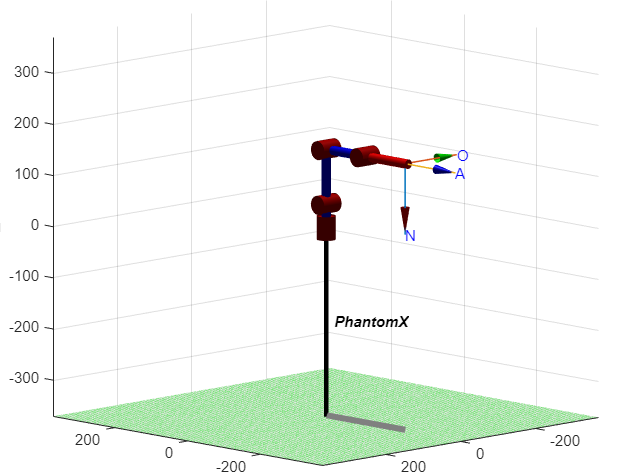

figure;
R.plot(q(elem,:),'noa')

view([-134 10])